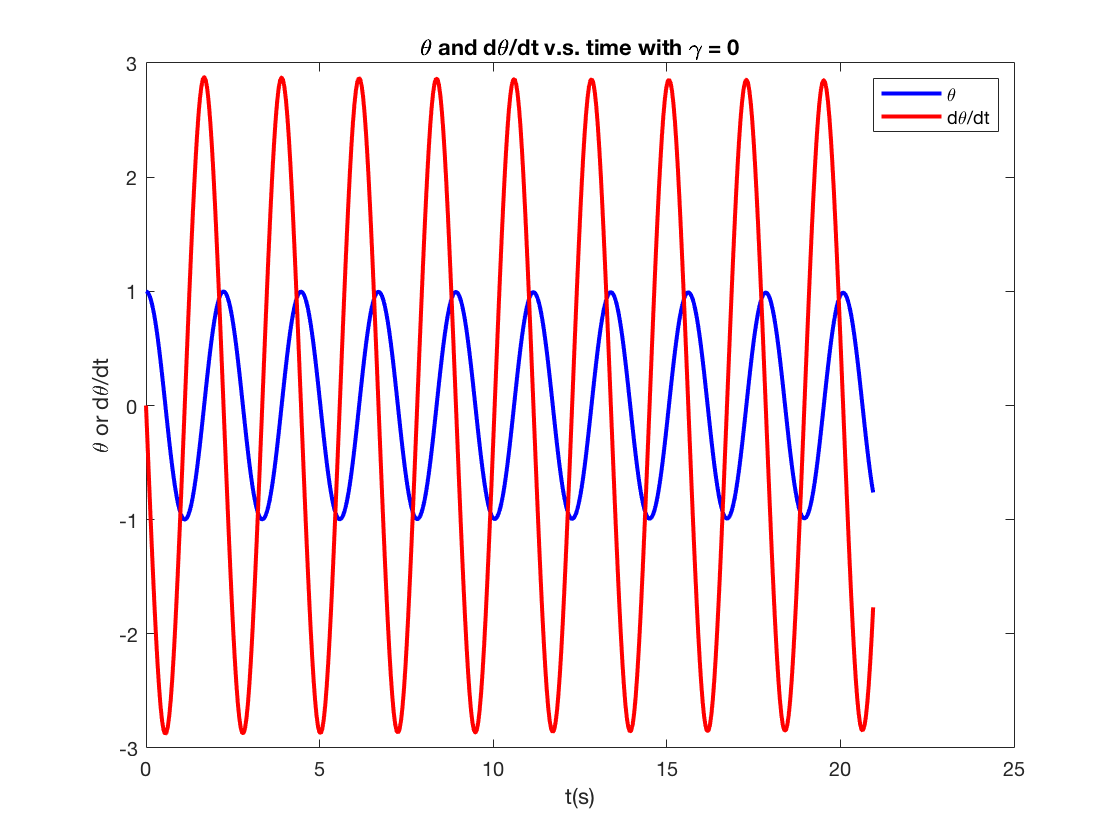


[T, sol] = damped_oscillator(3,0,1,0);

T_undamped = T;
omega_undamped = 2*pi/T_undamped;
disp(['Undamped period is ' num2str(T_undamped),', freq is ',num2str(omega_undamped)])

Undamped period is 2.2046, freq is 2.85


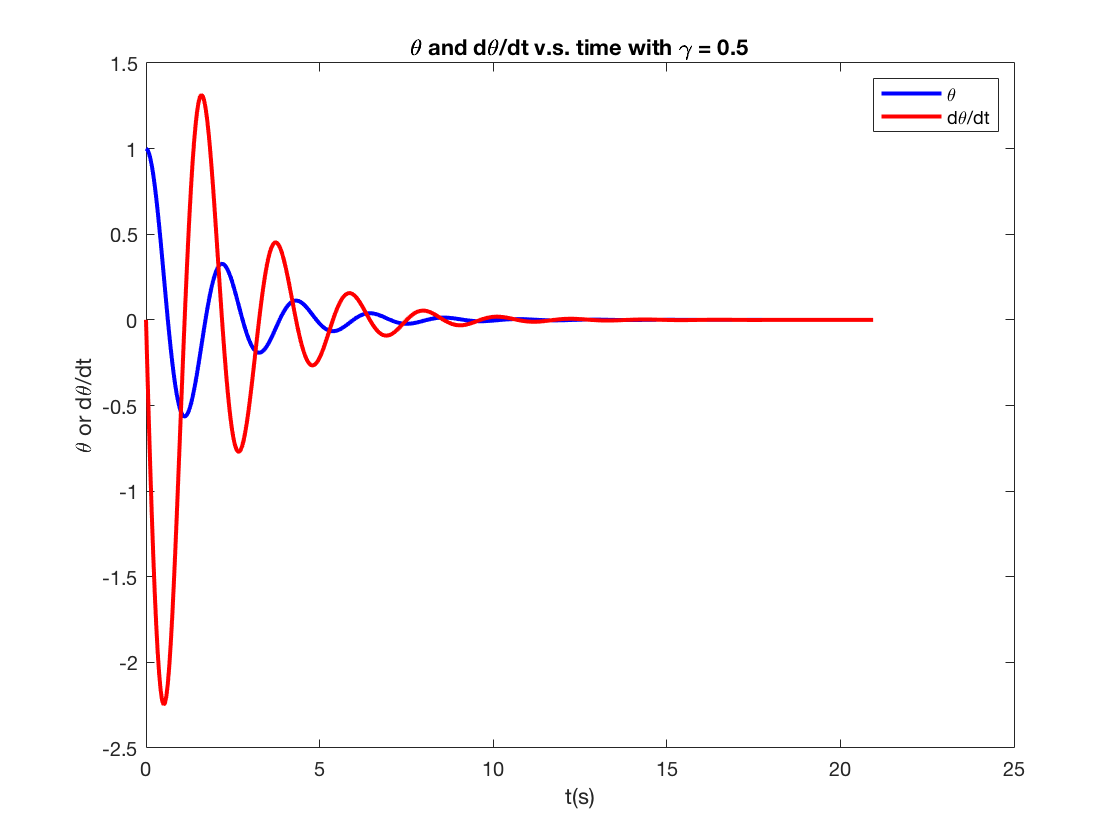

T = 2.1406

T ratio = 0.9709, ang. freq. ratio is 1.03


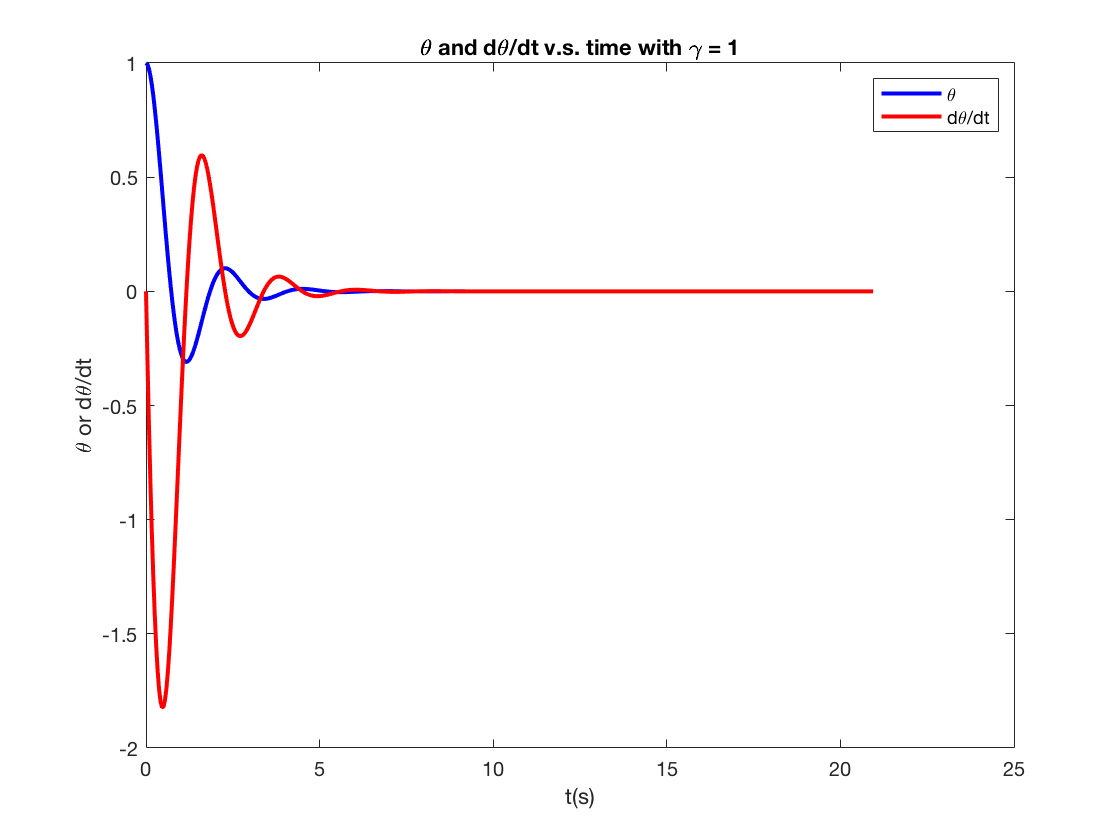

T = 2.2455

T ratio = 1.019, ang. freq. ratio is 0.9818


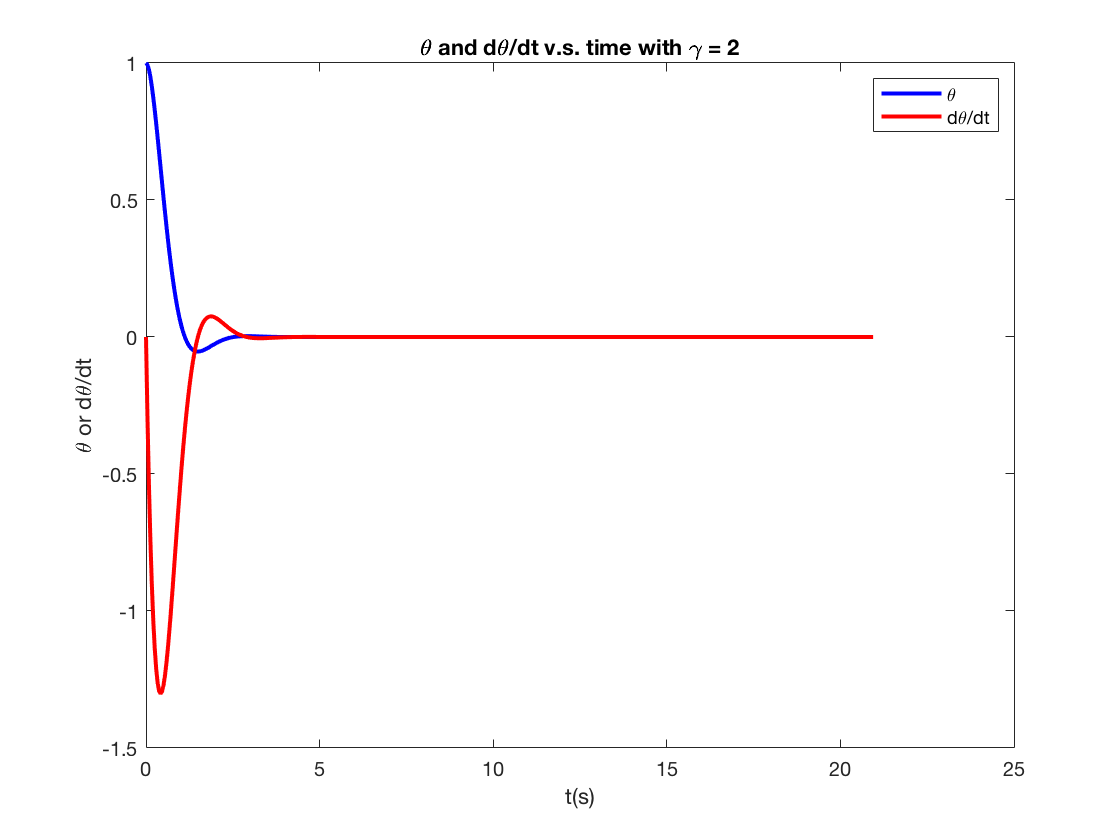

T = 2.9380

T ratio = 1.333, ang. freq. ratio is 0.7504


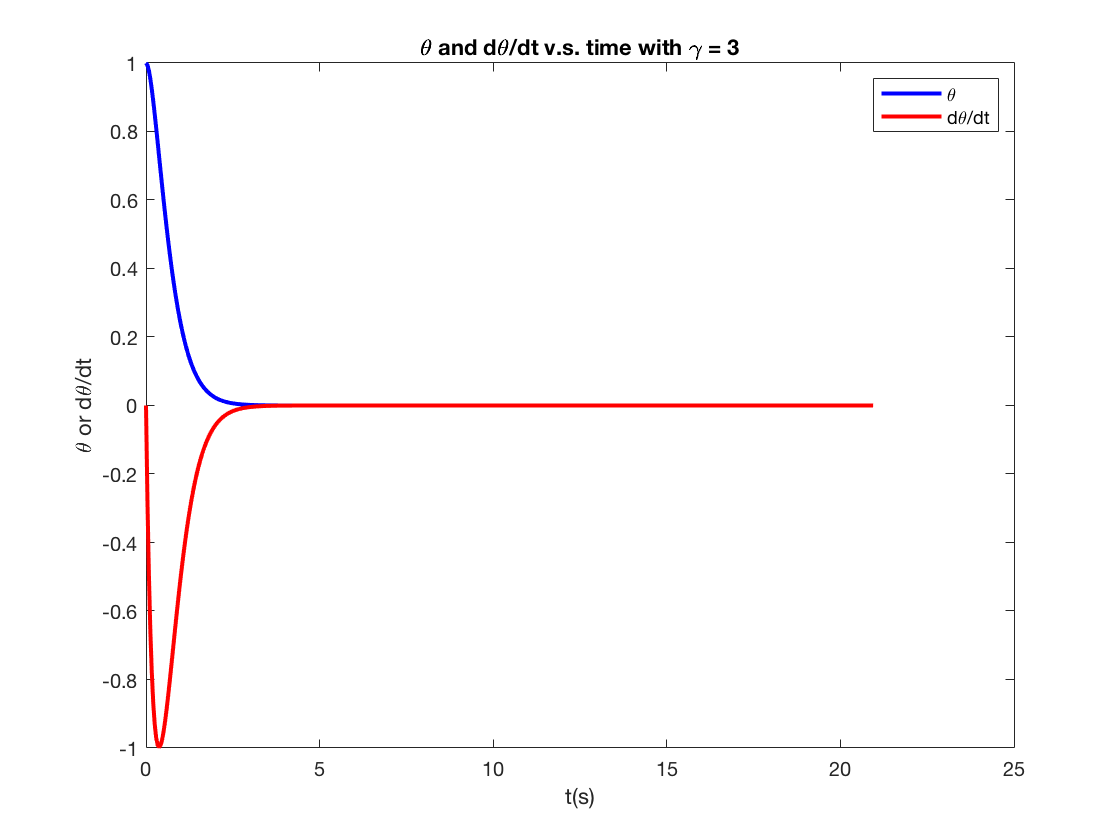

T = NaN

T ratio = NaN, ang. freq. ratio is NaN



gamma_list = [0.5,1,2,3];

for i=1:4
    [T, sol] = damped_oscillator(3,gamma_list(i),1,0);
    T
    omega = 2*pi/T;
    disp(['T ratio = ' num2str(T/T_undamped,4) ', ang. freq. ratio is ' num2str(omega...
    /omega_undamped,4)])
end

Here I set gamma = b / (2*m).

We expect the period to be larger with larger damping factor. But there is something wrong with gamma = 0.5.

My result shows, for gamma < 3, larger damping ratio makes period larger and angular frequency smaller. For gamma  = 3, no oscillation observed. 

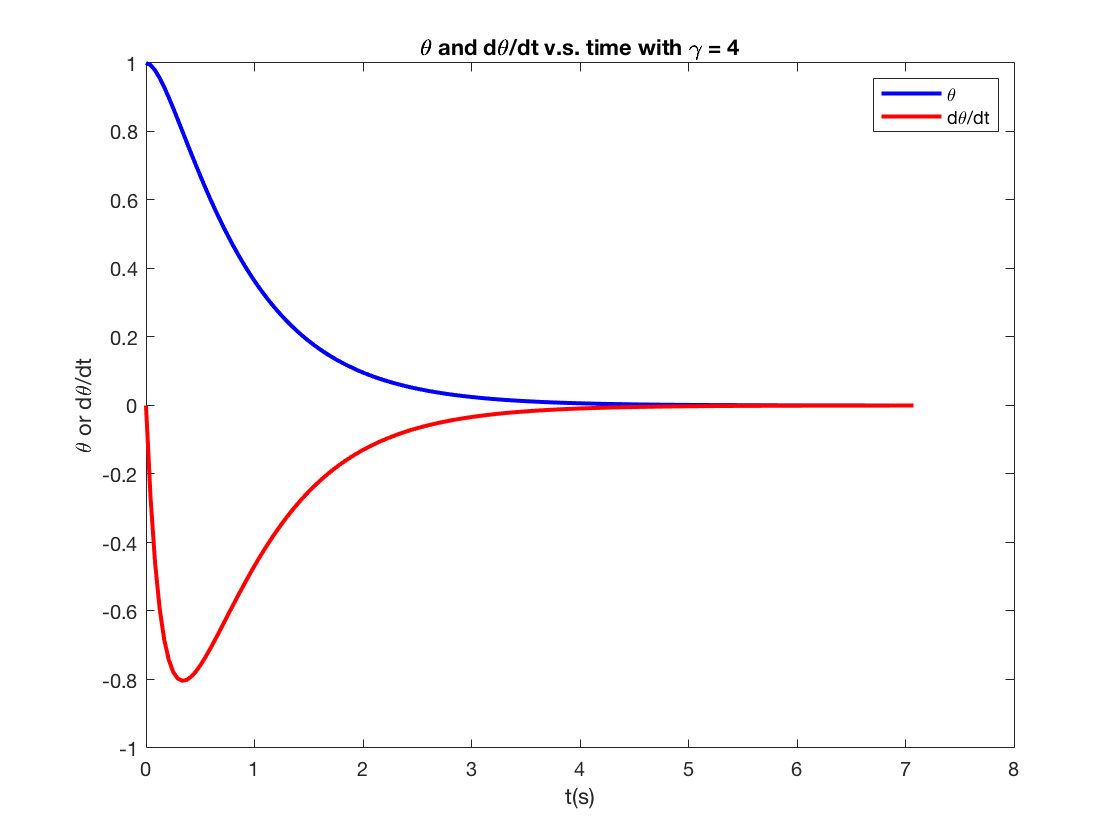

Terminal t = 7.0741 s.


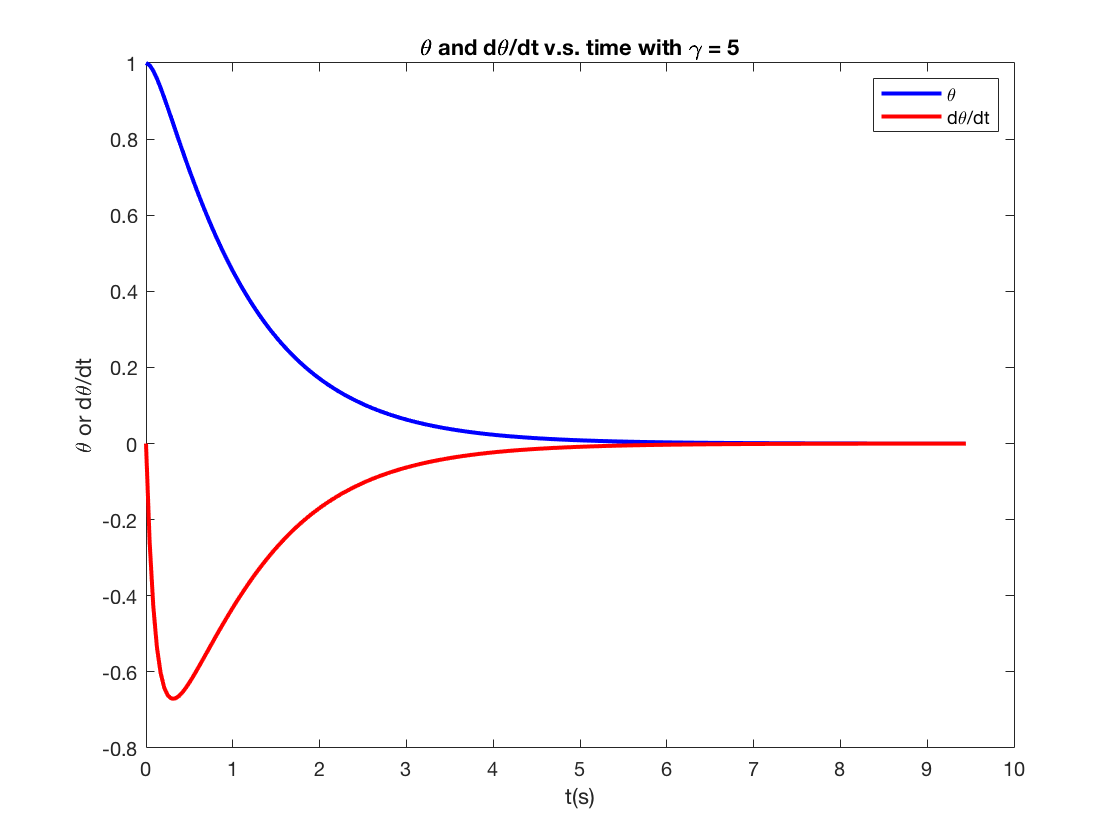

Terminal t = 9.4458 s.


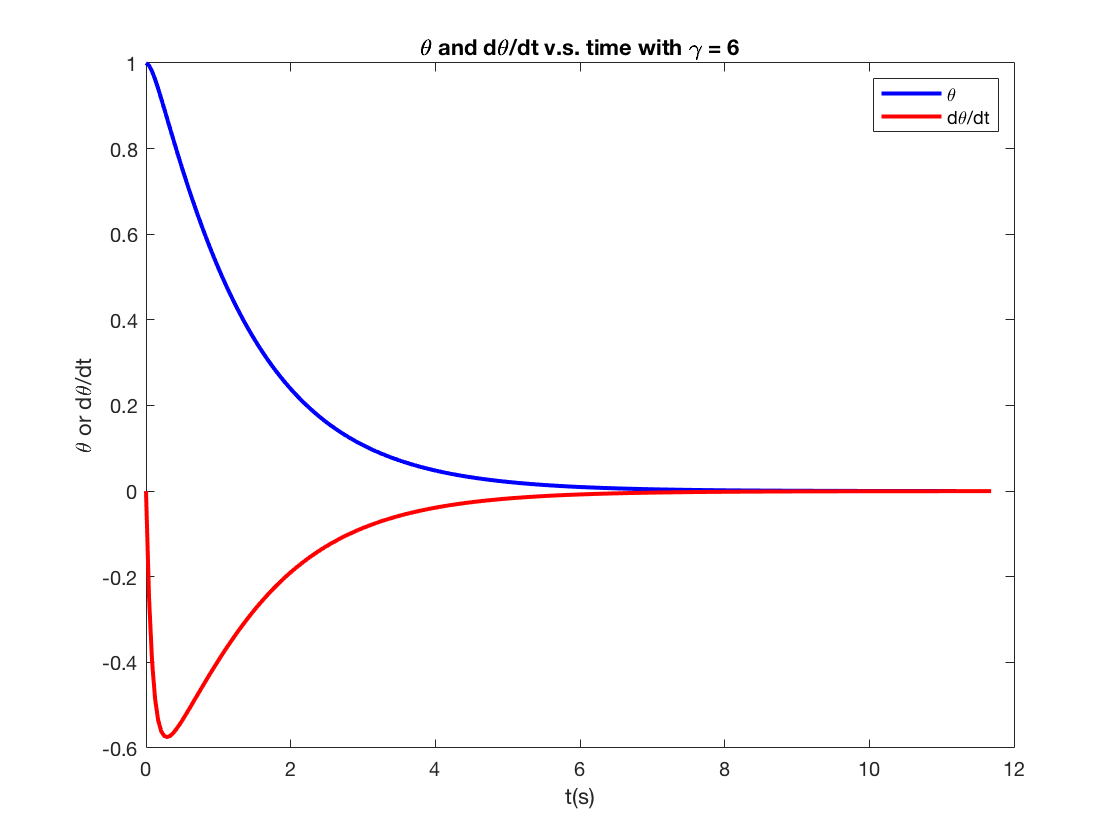

Terminal t = 11.6836 s.


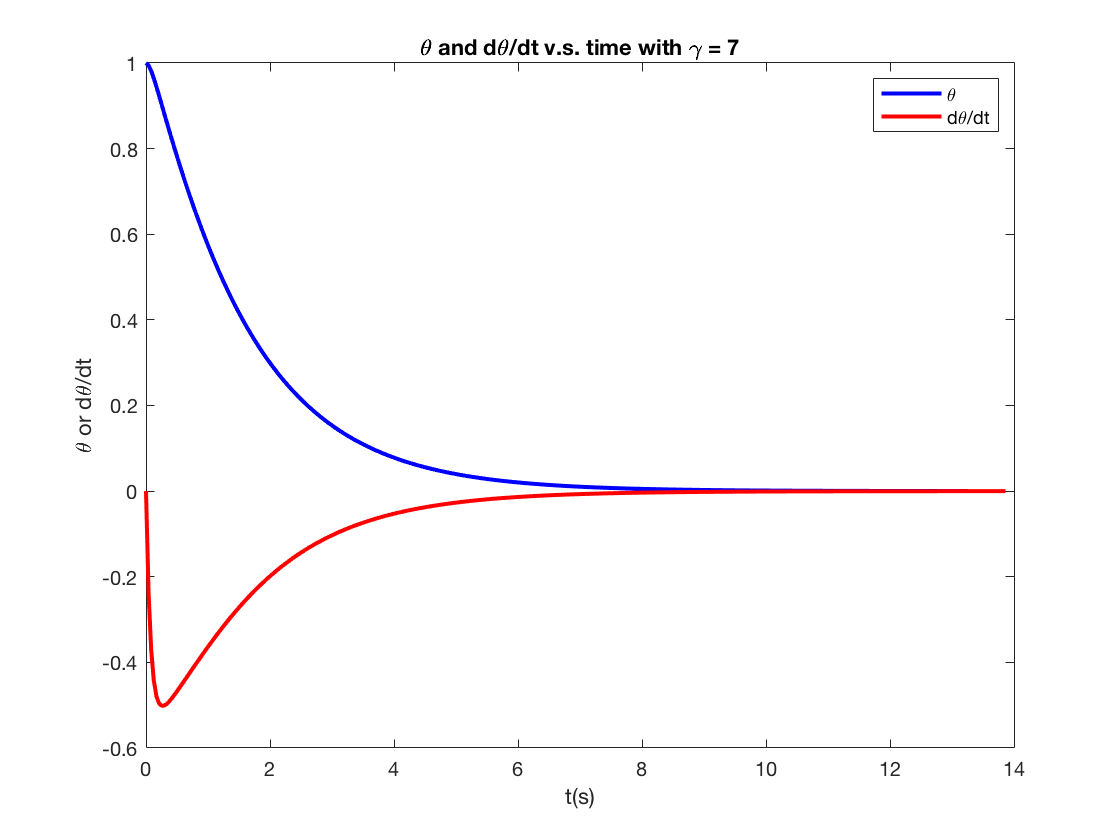

Terminal t = 13.8635 s.


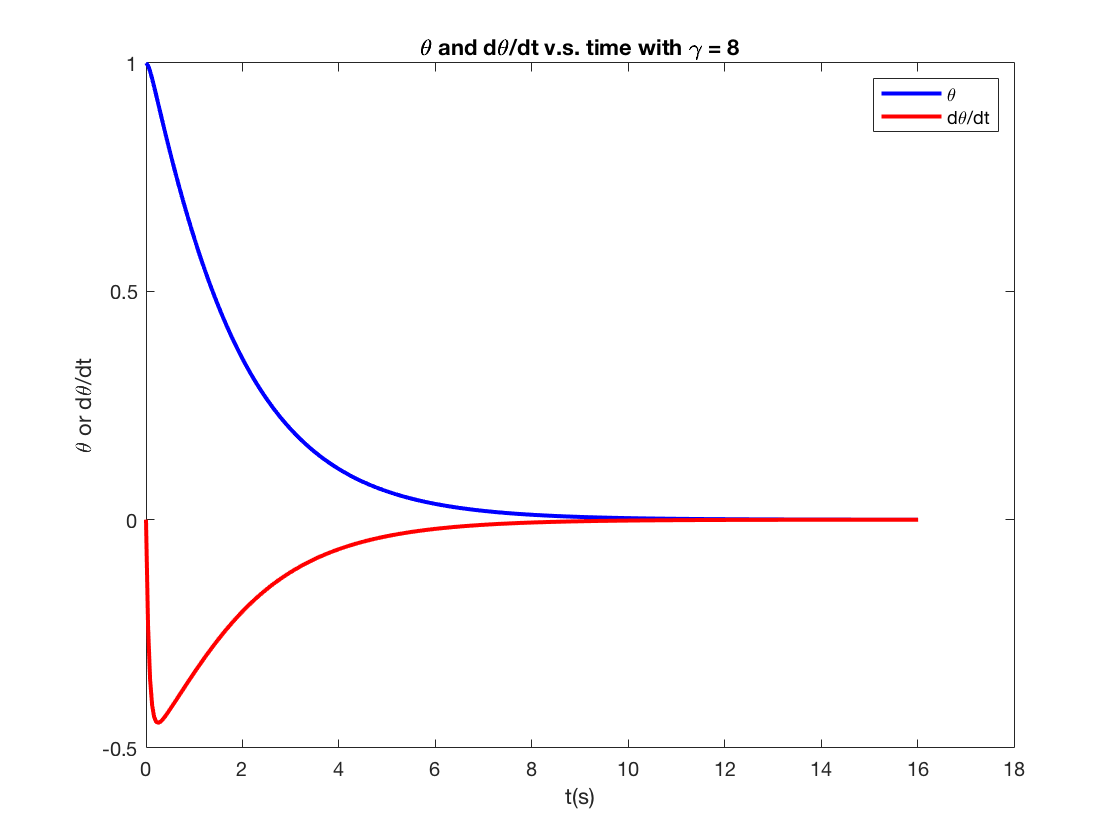

Terminal t = 16.0112 s.


gamma_list = [4,5,6,7,8];

for i=1:5
    [T, sol] = damped_oscillator(3,gamma_list(i),1.,0);
    disp(['Terminal t = ' num2str(sol(end,1)) ' s.'])
    
end

For gamma > = 3, no oscillation is observed, and larger gamma makes decay slower - terminal time is longer.

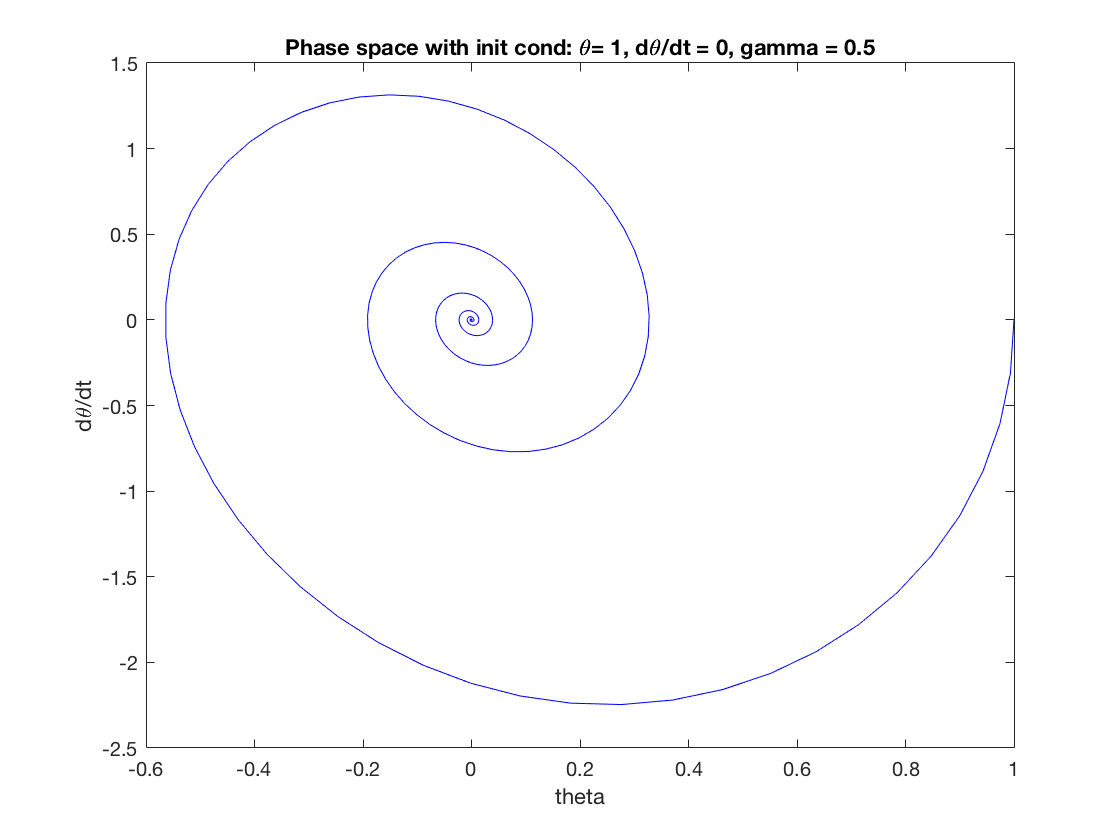

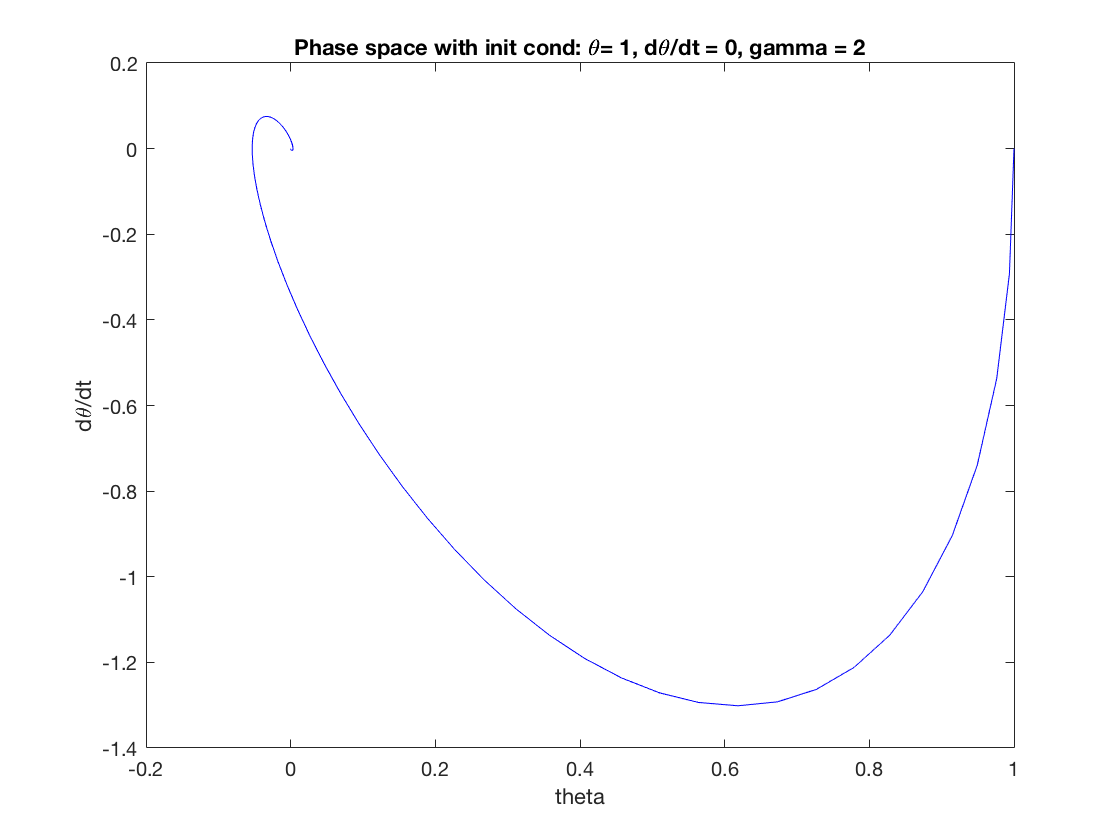

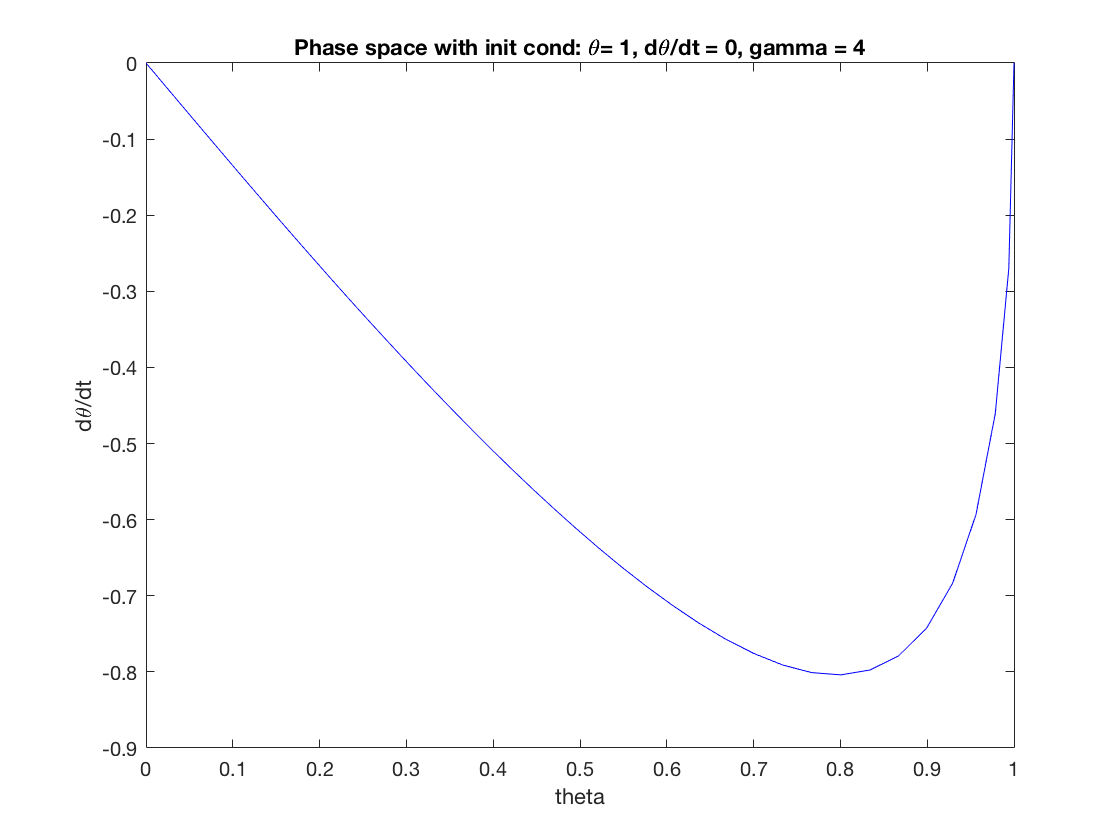

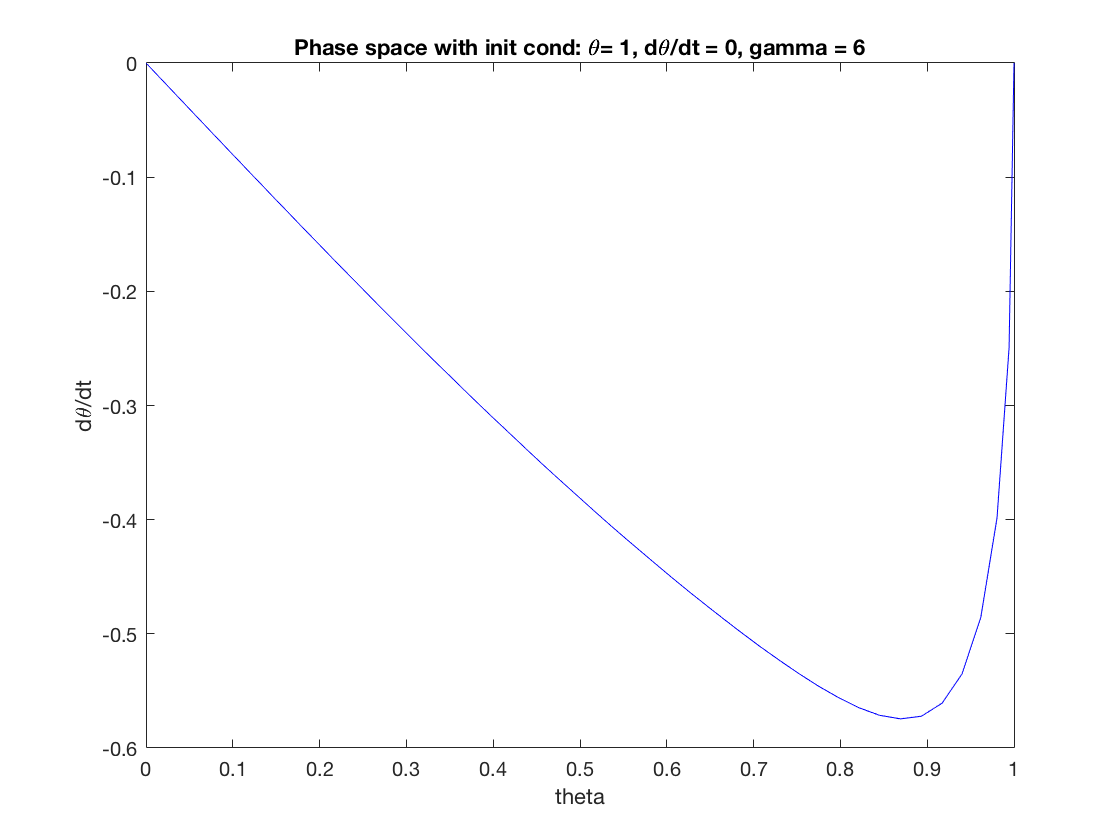

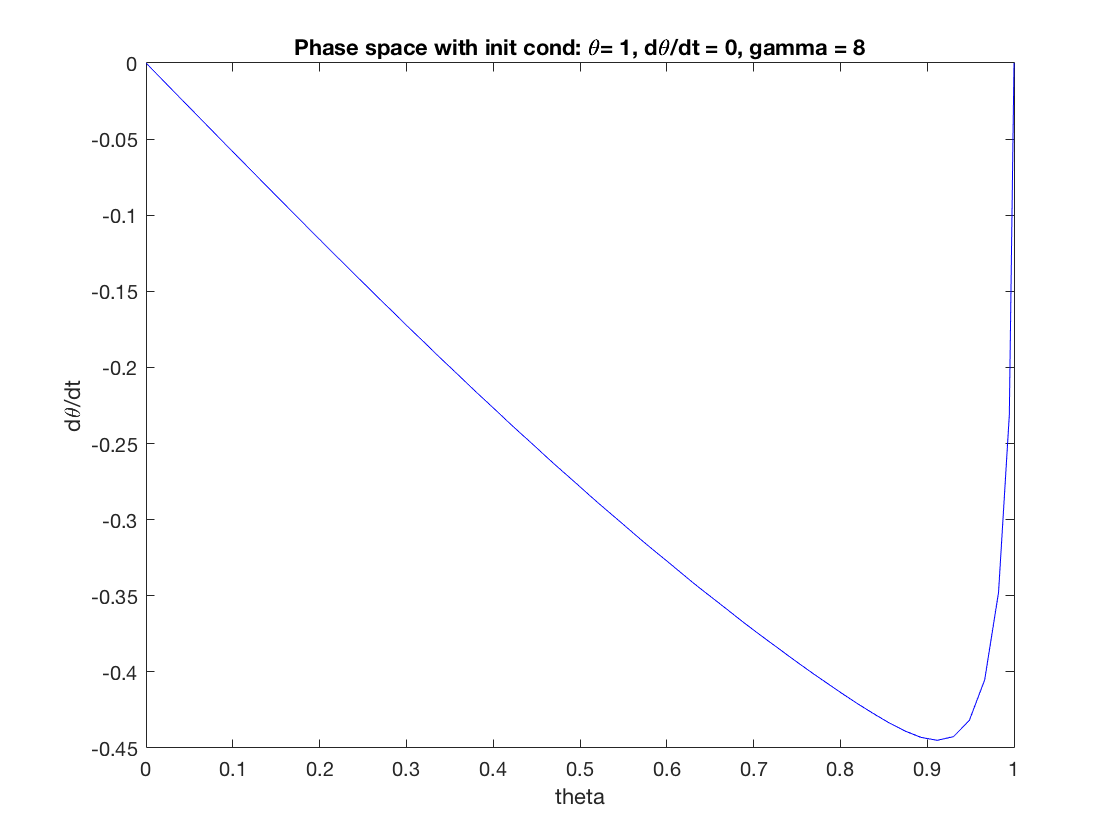

gamma_list = [0.5,2,4,6,8];

for i=1:5
    [T, sol] = damped_oscillator(3,gamma_list(i),1.,0.,0);
    figure
    plot(sol(:,2),sol(:,3),'b')
    title(['Phase space with init cond: \theta= 1, d\theta/dt = 0, gamma = ' num2str(gamma_list(i))])
    %xlim([-2,2])
    %ylim([-4,4])
    xlabel('theta')
    ylabel('d\theta/dt')
end

Qualitative features of phase diagram depends on gamma. If gamma is not big enough, pendulum will still oscillate and then come back to equilibrium - a swirl shape in phase diagram. If gamma is large(compared to omega0), pendulum will come back to equilibrium slowly without oscillation - a direct path to (0,0).